clear 
clc

bag = rosbag('planned_robot_pose_pt_205_1.bag');

bSel = select(bag,'Topic','/tf');
% 
msgStructs = readMessages(bSel,'DataFormat','struct');
%w = cellfun(@(m) double(m.Transforms.Transform.Translation.X),msgStructs);



msgStructs = cell2mat(msgStructs)

msgStructs = 5104×1 struct array with fields:
    MessageType
    Transforms


%time_init = double(msgStructs(1,1).Transforms.Header.Stamp.Sec);
t_ee_ref_position = []


t_ee_ref_position =

     []



time = [];
n = 0;
t_ee_ref_orientation = [];
link_7_position = [];
for i=1:length(msgStructs)
    c = size(msgStructs(i,1).Transforms);
    if c(2) == 1
        m = msgStructs(i,1).Transforms.Transform.Translation;
        t_ee_ref_position = cat(1,t_ee_ref_position,[m.X,m.Y,m.Z]);
        m = msgStructs(i,1).Transforms.Transform.Rotation;
        q = quat2eul([m.W, m.X,m.Y,m.Z],"ZYX")*180/pi;
        t_ee_ref_orientation = cat(1,t_ee_ref_orientation,q);
        time = cat(1,time,msgStructs(i,1).Transforms.Header.Stamp.Sec);
    else
        m = msgStructs(i,1).Transforms(7).Transform.Translation;
        link_7_position = cat(1,link_7_position,[m.X,m.Y,m.Z]);
%         time = cat(1,time,msgStructs(i,1).Transforms(7).Header.Stamp.Sec);
    end
     
end
    
% Transforms = msgStructs.Transforms
% Translation = Transforms.Transform.Translation
% Rotation = Transforms.Transform.Rotation

bag = rosbag('pose_normal_pt_205_1.bag');

bSel = select(bag,'Topic','/tf_array_out');
% 
msgStructs = readMessages(bSel,'DataFormat','struct');
x = cellfun(@(m) double(m.Poses.Position.X),msgStructs);
y = cellfun(@(m) double(m.Poses.Position.Y),msgStructs);
z = cellfun(@(m) double(m.Poses.Position.Z),msgStructs);

position_cloud = [x y z]

position_cloud =    -0.6760   -0.0159    0.0760
   -0.6754   -0.0164    0.0770
   -0.6761   -0.0164    0.0770
   -0.6757   -0.0167    0.0760
   -0.6753   -0.0160    0.0760
   -0.6761   -0.0164    0.0770
   -0.6757   -0.0163    0.0760
   -0.6756   -0.0159    0.0760
   -0.6760   -0.0163    0.0760
   -0.6753   -0.0163    0.0760


mean_pos_cloud = mean(position_cloud)

mean_pos_cloud =    -0.6758   -0.0163    0.0765



x = cellfun(@(m) double(m.Poses.Orientation.X),msgStructs);
y = cellfun(@(m) double(m.Poses.Orientation.Y),msgStructs);
z = cellfun(@(m) double(m.Poses.Orientation.Z),msgStructs);
w = cellfun(@(m) double(m.Poses.Orientation.W),msgStructs);
quaternion = [w,x , y, z]

quaternion =    -0.1911    0.7036    0.6706    0.1373
   -0.1926    0.7033    0.6703    0.1380
   -0.1917    0.7031    0.6701    0.1409
   -0.1916    0.7029    0.6700    0.1428
   -0.1919    0.7032    0.6702    0.1395
   -0.1926    0.7031    0.6701    0.1395
   -0.1927    0.7033    0.6703    0.1375
   -0.1913    0.7030    0.6700    0.1427
   -0.1920    0.7033    0.6703    0.1386
   -0.1957    0.7024    0.6695    0.1418


mean_quat = mean(quaternion)

mean_quat =    -0.1922    0.7032    0.6701    0.1394


orientation_rpy = quat2eul(quaternion,'ZYX')*180/pi

orientation_rpy =    85.9556  -26.7057 -174.5585
   85.9253  -26.8954 -174.4690
   85.9986  -27.0707 -174.8049
   86.0299  -27.2230 -174.9614
   85.9687  -26.9609 -174.6632
   85.9504  -27.0214 -174.5996
   85.9143  -26.8617 -174.4200
   86.0381  -27.1909 -174.9911
   85.9517  -26.8923 -174.5816
   85.9064  -27.4642 -174.5044


mean_rpy = mean(orientation_rpy)

mean_rpy =    85.9488  -26.9840 -174.6247


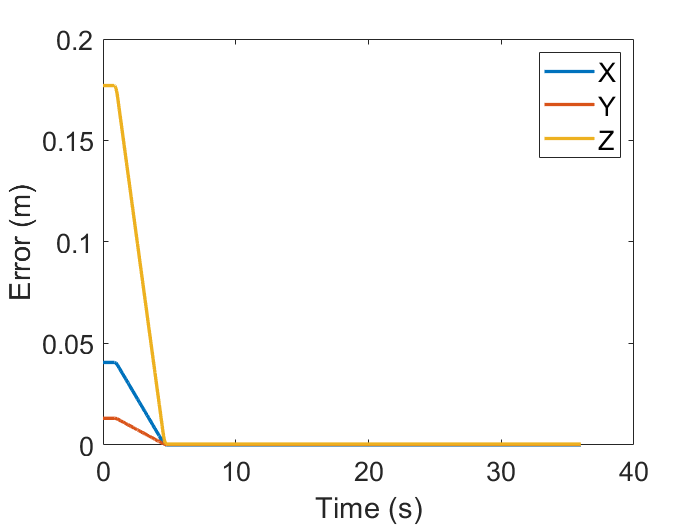

clf
error_position_expected = abs(t_ee_ref_position - mean_pos_cloud);

error_orientation_expected = abs(t_ee_ref_orientation - mean_rpy);
time_init = time(1,1);
time_final = time(length(time),1);
n_sec = double(time_final-time_init);
n = double(length(time));
% time=linspace(0,n_sec,n);
t = linspace(0,n_sec,n);
figure

plot(t,error_position_expected,'LineWidth',2)
ax = gca;
ylabel("Error (m)","FontSize",12)
xlabel("Time (s)","FontSize",12)
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
legend(["X","Y","Z"],'FontSize',16)

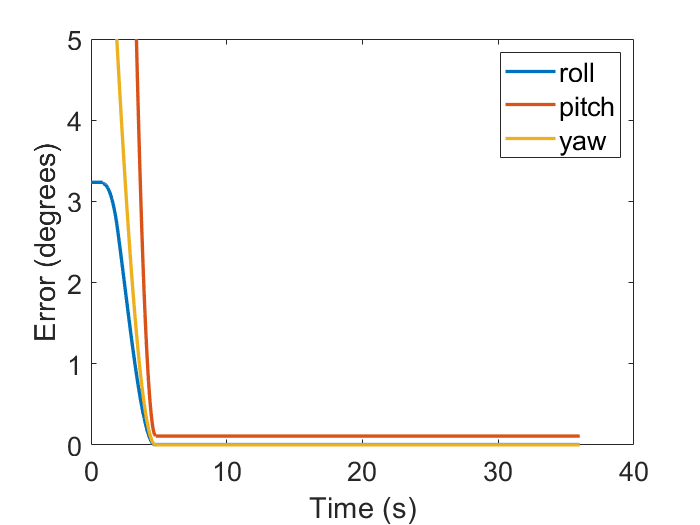

error_orientation_expected = abs(t_ee_ref_orientation - mean_rpy);
plot(t,error_orientation_expected,'LineWidth',2)
ax = gca;
ylabel("Error (degrees)",'FontSize',12)
xlabel("Time (s)",'FontSize',12)

ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
legend(["roll","pitch","yaw"],'fontsize',16)
ylim([0 5])